# Exercises 7.2

2. List all terms needed to generate the shape functions for a serendipity quadrilateral element with 12 nodes. Use computersoftware to compute all polynomials coefficients.

clear all
clc

n = 4;

xi = linspace (-1, 1, n);
eta = xi';

no = zeros(12:2);

no( 1, :) = [xi(1) eta(1)];
no( 2, :) = [xi(4) eta(1)];
no( 3, :) = [xi(4) eta(4)];
no( 4, :) = [xi(1) eta(4)];
no( 5, :) = [xi(2) eta(1)];
no( 6, :) = [xi(3) eta(1)];
no( 7, :) = [xi(4) eta(2)];
no( 8, :) = [xi(4) eta(3)];
no( 9, :) = [xi(3) eta(4)];
no(10, :) = [xi(2) eta(4)];
no(11, :) = [xi(1) eta(3)];
no(12, :) = [xi(1) eta(2)];
No = zeros (12:12);

for i = 1: 12
    No(i , :) = [1, no(i, 1), no(i, 2), no(i, 1)*no(i, 2), (no(i, 1))^2, ... 
        (no(i, 2))^2, (no(i, 1))^2*(no(i, 2)), (no(i, 1))*(no(i, 2))^2, ...
        (no(i, 1))^3, (no(i, 2))^3, (no(i, 1))^3*(no(i, 2)), (no(i, 1))*(no(i, 2))^3];
end

C = inv(No);

syms xi eta

for i = 1: 12
n = C(:, i) .* [1, xi, eta, xi*eta, xi^2, ...
    eta^2, xi^2*eta, xi*eta^2, xi^3, eta^3, ...
    xi^3*eta, xi*eta^3]';
N(i, 1) = sum(n);
end
simplify (N)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\left(\bar{\eta }-1\right)\,\left(\bar{\xi }-1\right)\,\sigma_{1}}{32}\\ -\frac{\left(\bar{\eta }-1\right)\,\left(\bar{\xi }+1\right)\,\sigma_{1}}{32}\\ \frac{\left(\bar{\eta }+1\right)\,\left(\bar{\xi }+1\right)\,\sigma_{1}}{32}\\ -\frac{\left(\bar{\eta }+1\right)\,\left(\bar{\xi }-1\right)\,\sigma_{1}}{32}\\ \frac{9\,\left(\bar{\eta }-1\right)\,\sigma_{3}}{32}\\ -\frac{9\,\left(\bar{\eta }-1\right)\,\sigma_{2}}{32}\\ -\frac{9\,\left(\bar{\xi }+1\right)\,\sigma_{5}}{32}\\ \frac{9\,\left(\bar{\xi }+1\right)\,\sigma_{4}}{32}\\ \frac{9\,\left(\bar{\eta }+1\right)\,\sigma_{2}}{32}\\ -\frac{9\,\left(\bar{\eta }+1\right)\,\sigma_{3}}{32}\\ -\frac{9\,\left(\bar{\xi }-1\right)\,\sigma_{4}}{32}\\ \frac{9\,\left(\bar{\xi }-1\right)\,\sigma_{5}}{32} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=9\,{\left(\bar{\eta }\right)}^{2}+9\,{\left(\bar{\xi }\right)}^{2}-10\\ \sigma_{2}=-\sigma_{6}-{\left(\bar{\xi }\right)}^{2}+3\,\bar{\xi }+1\\ \sigma_{3}=-\sigma_{6}+{\left(\bar{\xi }\right)}^{2}+3\,\bar{\xi }-1\\ \sigma_{4}=-\sigma_{7}-{\left(\bar{\eta }\right)}^{2}+3\,\bar{\eta }+1\\ \sigma_{5}=-\sigma_{7}+{\left(\bar{\eta }\right)}^{2}+3\,\bar{\eta }-1\\ \sigma_{6}=3\,{\left(\bar{\xi }\right)}^{3}\\ \sigma_{7}=3\,{\left(\bar{\eta }\right)}^{3} \end{array}$$

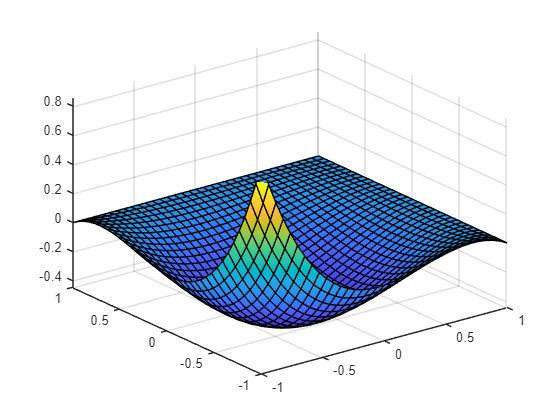

fsurf(N(1),[-1 1 -1 1])

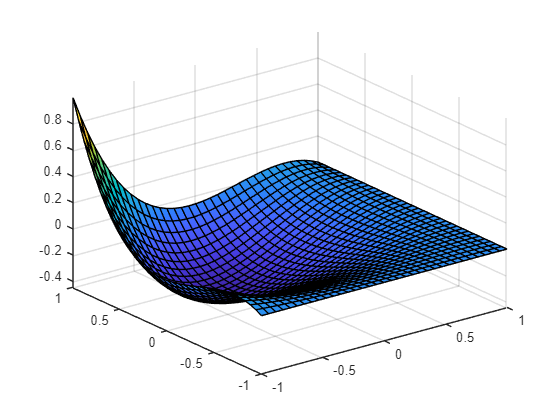

fsurf(N(2),[-1 1 -1 1])

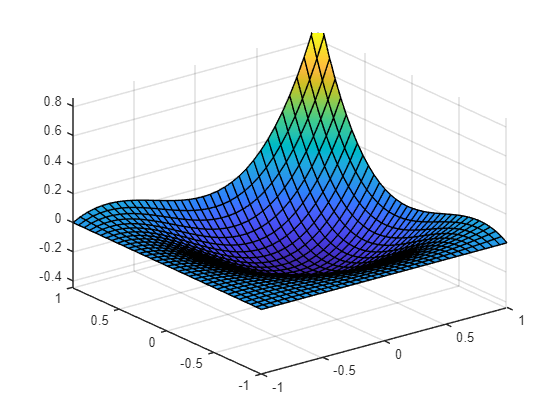

fsurf(N(3),[-1 1 -1 1])

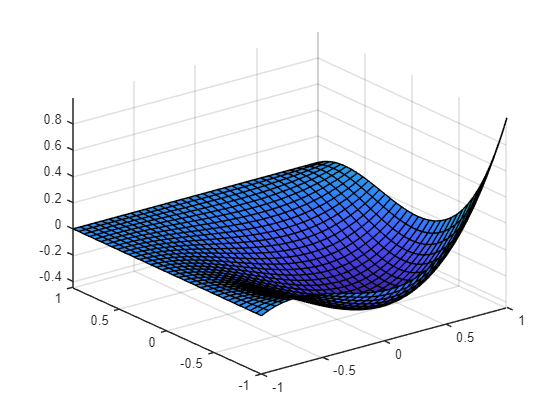

fsurf(N(4),[-1 1 -1 1])

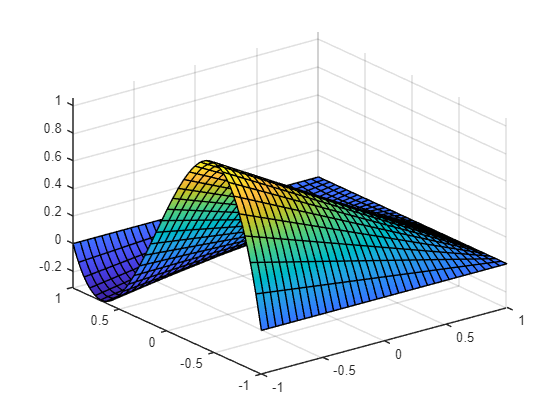

fsurf(N(5),[-1 1 -1 1])

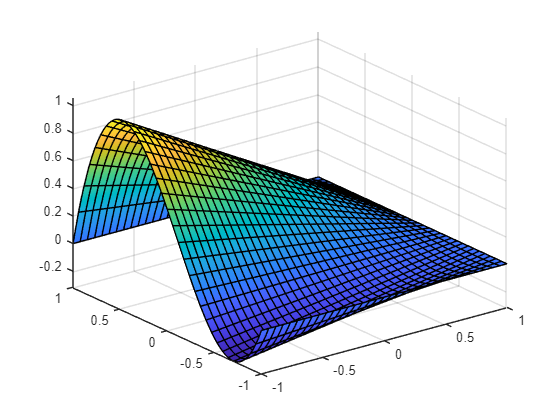

fsurf(N(6),[-1 1 -1 1])

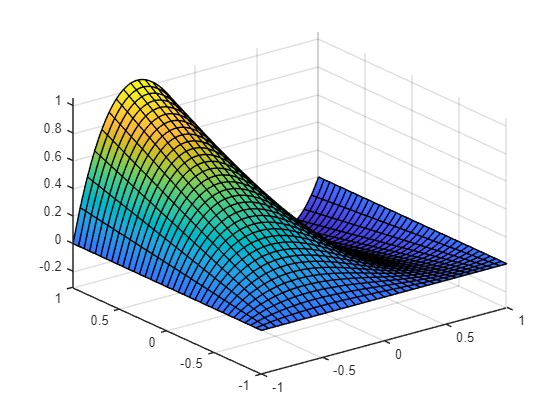

fsurf(N(7),[-1 1 -1 1])

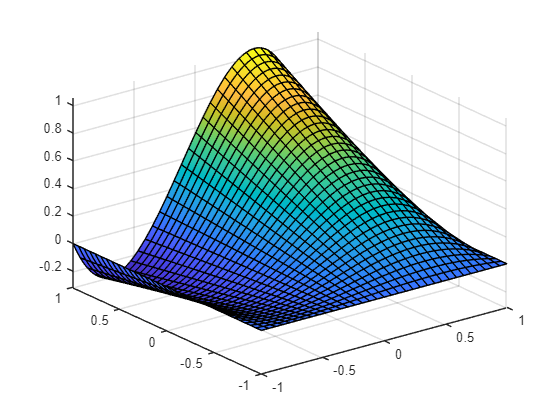

fsurf(N(8),[-1 1 -1 1])

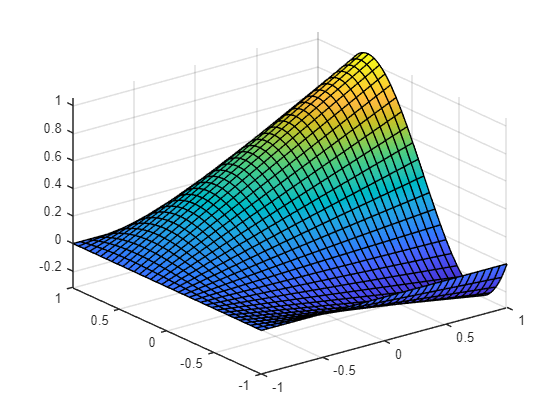

fsurf(N(9),[-1 1 -1 1])

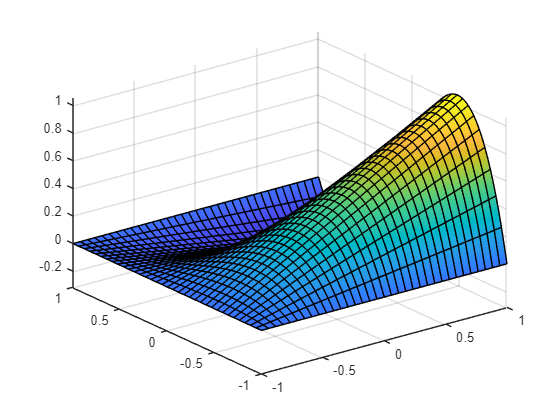

fsurf(N(10),[-1 1 -1 1])

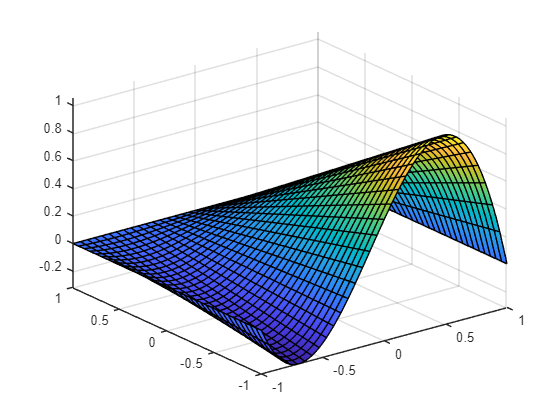

fsurf(N(11),[-1 1 -1 1])

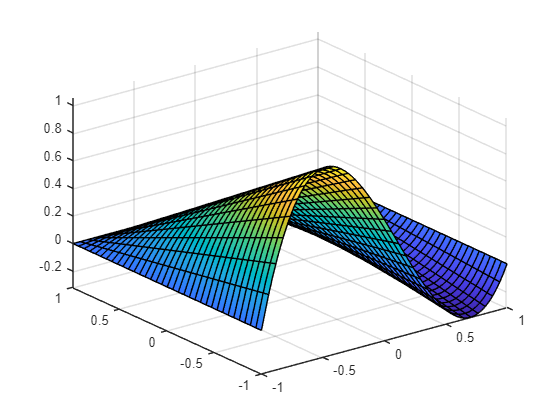

fsurf(N(12),[-1 1 -1 1])